Retrieve incident of close interaction with the Agonist and Neutral Cup in combined SDT

% Close1A=ensb_BehavA.CloseEvents in SDT1;
% Close1N=ensb_BehavN.CloseEvents in SDT1;
% Close2A=ensb_BehavA.CloseEvents in SDT2;
% Close2N=ensb_BehavN.CloseEvents in SDT2;


Compute mean CaImg data during different close events

% ensbA during Close1A & Close1B

NumClose1A=numel(Close1A);
NumClose1N=numel(Close1N);

mNeuP_A1A(NumClose1A,41)=0;
mNeuP_N1A(NumClose1A,41)=0;
mNeuP_A1N(NumClose1N,41)=0;
mNeuP_N1N(NumClose1N,41)=0;
sumNeuP_A1A(NumClose1A)=0;
sumNeuP_N1A(NumClose1A)=0;
sumNeuP_A1N(NumClose1N)=0;
sumNeuP_N1N(NumClose1N)=0;

for i=1:NumClose1A
    mNeuP_A1A(i,:)=sum(NeuP(ensb_BehavA40.ensb0ID,Close1A(i)-25:Close1A(i)+15))/numel(ensb_BehavA40.ensb0ID);
    mNeuP_N1A(i,:)=sum(NeuP(ensb_BehavN40.ensb0ID,Close1A(i)-25:Close1A(i)+15))/numel(ensb_BehavN40.ensb0ID);
    sumNeuP_A1A(i)=sum(mNeuP_A1A(i,:));
    sumNeuP_N1A(i)=sum(mNeuP_N1A(i,:));
end

mmNeuP_A1A=mean(mNeuP_A1A);
mmNeuP_N1A=mean(mNeuP_N1A);
sdNeuP_A1A=std(mNeuP_A1A);
sdNeuP_N1A=std(mNeuP_N1A);
semNeuP_A1A=sdNeuP_A1A/sqrt(NumClose1A-1);
semNeuP_N1A=sdNeuP_N1A/sqrt(NumClose1A-1);

for j=1:NumClose1N
    mNeuP_A1N(j,:)=sum(NeuP(ensb_BehavA40.ensb0ID,Close1N(j)-25:Close1N(j)+15))/numel(ensb_BehavA40.ensb0ID);
    mNeuP_N1N(j,:)=sum(NeuP(ensb_BehavN40.ensb0ID,Close1N(j)-25:Close1N(j)+15))/numel(ensb_BehavN40.ensb0ID);
    sumNeuP_A1N(j)=sum(mNeuP_A1N(j,:));
    sumNeuP_N1N(j)=sum(mNeuP_N1N(j,:));
end

mmNeuP_A1N=mean(mNeuP_A1N);
mmNeuP_N1N=mean(mNeuP_N1N);
sdNeuP_A1N=std(mNeuP_A1N);
sdNeuP_N1N=std(mNeuP_N1N);
semNeuP_A1N=sdNeuP_A1N/sqrt(NumClose1N-1);
semNeuP_N1N=sdNeuP_N1N/sqrt(NumClose1N-1);

totalNeuP_A1A=sum(mmNeuP_A1A)

totalNeuP_A1A = 0.4429

totalNeuP_N1A=sum(mmNeuP_N1A)

totalNeuP_N1A = 0.3304

totalNeuP_N1N=sum(mmNeuP_N1N)

totalNeuP_N1N = 0.6025

totalNeuP_A1N=sum(mmNeuP_A1N)

totalNeuP_A1N = 0.4612


[h1A,p1A]=ttest(sumNeuP_A1A,sumNeuP_N1A)

h1A = 0

p1A = 0.1569

[h1N,p1N]=ttest(sumNeuP_N1N,sumNeuP_A1N)

h1N = 0

p1N = 0.1860


% ensbA during Close2A & Close2B

NumClose2A=numel(Close2A);
NumClose2N=numel(Close2N);

mNeuP_A2A(NumClose2A,41)=0;
mNeuP_N2A(NumClose2A,41)=0;
mNeuP_A2N(NumClose2N,41)=0;
mNeuP_N2N(NumClose2N,41)=0;
sumNeuP_A2A(NumClose2A)=0;
sumNeuP_N2A(NumClose2A)=0;
sumNeuP_A2N(NumClose2N)=0;
sumNeuP_N2N(NumClose2N)=0;

for i=1:NumClose2A
    mNeuP_A2A(i,:)=sum(NeuP(ensb_BehavA40.ensb0ID,Close2A(i)-25:Close2A(i)+15))/numel(ensb_BehavA40.ensb0ID);
    mNeuP_N2A(i,:)=sum(NeuP(ensb_BehavN40.ensb0ID,Close2A(i)-25:Close2A(i)+15))/numel(ensb_BehavN40.ensb0ID);
    sumNeuP_A2A(i)=sum(mNeuP_A2A(i,:));
    sumNeuP_N2A(i)=sum(mNeuP_N2A(i,:));
end

mmNeuP_A2A=mean(mNeuP_A2A);
mmNeuP_N2A=mean(mNeuP_N2A);
sdNeuP_A2A=std(mNeuP_A2A);
sdNeuP_N2A=std(mNeuP_N2A);
semNeuP_A2A=sdNeuP_A2A/sqrt(NumClose2A-1);
semNeuP_N2A=sdNeuP_N2A/sqrt(NumClose2A-1);

for j=1:NumClose2N
    mNeuP_A2N(j,:)=sum(NeuP(ensb_BehavA40.ensb0ID,Close2N(j)-25:Close2N(j)+15))/numel(ensb_BehavA40.ensb0ID);
    mNeuP_N2N(j,:)=sum(NeuP(ensb_BehavN40.ensb0ID,Close2N(j)-25:Close2N(j)+15))/numel(ensb_BehavN40.ensb0ID);
    sumNeuP_A2N(j)=sum(mNeuP_A2N(j,:));
    sumNeuP_N2N(j)=sum(mNeuP_N2N(j,:));
end

mmNeuP_A2N=mean(mNeuP_A2N);
mmNeuP_N2N=mean(mNeuP_N2N);
sdNeuP_A2N=std(mNeuP_A2N);
sdNeuP_N2N=std(mNeuP_N2N);
semNeuP_A2N=sdNeuP_A2N/sqrt(NumClose2N-1);
semNeuP_N2N=sdNeuP_N2N/sqrt(NumClose2N-1);

totalNeuP_A2A=sum(mmNeuP_A2A)

totalNeuP_A2A = 0.7175

totalNeuP_N2A=sum(mmNeuP_N2A)

totalNeuP_N2A = 0.2440

totalNeuP_N2N=sum(mmNeuP_N2N)

totalNeuP_N2N = 0.8261

totalNeuP_A2N=sum(mmNeuP_A2N)

totalNeuP_A2N = 0.2038


[h2A,p2A]=ttest(sumNeuP_A2A,sumNeuP_N2A)

h2A = 1

p2A = 1.3664e-05

[h2N,p2N]=ttest(sumNeuP_N2N,sumNeuP_A2N)

h2N = 1

p2N = 7.6453e-07

Plotting results

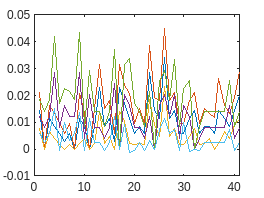

 
figure
plot(mmNeuP_A1A)
hold on
plot(mmNeuP_A1A+semNeuP_A1A)
plot(mmNeuP_A1A-semNeuP_A1A)
plot(mmNeuP_A1N)
plot(mmNeuP_A1N+semNeuP_A1N)
plot(mmNeuP_A1N-semNeuP_A1N)

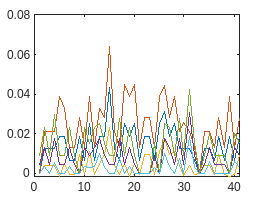


filename=horzcat(segment.mouseID,'_',segment.session,'_A1AvA1N40.fig');
% saveas(gcf,filename)

figure
plot(mmNeuP_N1N)
hold on
plot(mmNeuP_N1N+semNeuP_N1N)
plot(mmNeuP_N1N-semNeuP_N1N)
plot(mmNeuP_N1A)
plot(mmNeuP_N1A+semNeuP_N1A)
plot(mmNeuP_N1A-semNeuP_N1A)

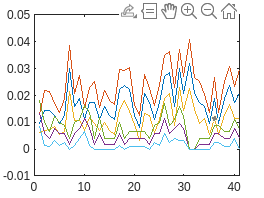

filename=horzcat(segment.mouseID,'_',segment.session,'_N1NvN1A40.fig');
% saveas(gcf,filename)

figure
plot(mmNeuP_A2A)
hold on
plot(mmNeuP_A2A+semNeuP_A2A)
plot(mmNeuP_A2A-semNeuP_A2A)
plot(mmNeuP_A2N)
plot(mmNeuP_A2N+semNeuP_A2N)
plot(mmNeuP_A2N-semNeuP_A2N)

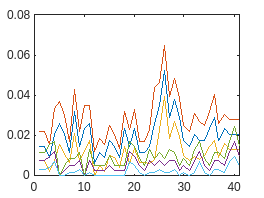

filename=horzcat(segment.mouseID,'_',segment.session,'_A2AvA2N40.fig');
% saveas(gcf,filename)

figure

plot(mmNeuP_N2N)
hold on
plot(mmNeuP_N2N+semNeuP_N2N)
plot(mmNeuP_N2N-semNeuP_N2N)
plot(mmNeuP_N2A)
plot(mmNeuP_N2A+semNeuP_N2A)
plot(mmNeuP_N2A-semNeuP_N2A)

filename=horzcat(segment.mouseID,'_',segment.session,'_N2NvN2A40.fig');
% saveas(gcf,filename)

% filename=horzcat(segment.mouseID,'_',segment.session,'_freqAnalysis40.mat');
% save(filename,"NumClose1A","NumClose1N","NumClose2A","NumClose2N")
% save(filename,"mNeuP_A1A","mNeuP_A1N","mNeuP_N1A","mNeuP_N1N","mNeuP_A2A","mNeuP_A2N","mNeuP_N2A","mNeuP_N2N","-append")
% save(filename,"mmNeuP_A1A","mmNeuP_A1N","mmNeuP_N1A","mmNeuP_N1N","mmNeuP_A2A","mmNeuP_A2N","mmNeuP_N2A","mmNeuP_N2N","-append")
% save(filename,"sdNeuP_A1A","sdNeuP_A1N","sdNeuP_N1A","sdNeuP_N1N","sdNeuP_A2A","sdNeuP_A2N","sdNeuP_N2A","sdNeuP_N2N","-append")
% save(filename,"semNeuP_A1A","semNeuP_A1N","semNeuP_N1A","semNeuP_N1N","semNeuP_A2A","semNeuP_A2N","semNeuP_N2A","semNeuP_N2N","-append")
% save(filename,"totalNeuP_A1A","totalNeuP_A1N","totalNeuP_N1A","totalNeuP_N1N","totalNeuP_A2A","totalNeuP_A2N","totalNeuP_N2A","totalNeuP_N2N","-append")
% save(filename,"h1A","h1N","h2A","h2N","p1A","p1N","p2A","p2N","-append")
